Review from week 1

Scalars:

a = 1;

Vectors/Arrays:

dist = [180 210 140 170 160];

Matrices:

scores = [ 98 85 93; 78 81 82; 65 72 67; 88 89 91; 99 96 98];

Indexing  

Matrix(x,y) --> x = rows, y = columns

Row 1, all columns:

scores(1,:)

ans =     98    85    93


 All rows, column 1: 

scores(:,1)

ans =     98
    78
    65
    88
    99


Performing functions (rather than operations) on vectors

Make a vector:

area = [1 4 9 16 25]

area =      1     4     9    16    25


The function sqrt(area) performs element wise square root operation (*note this assumes elements in vector 'area' represent perfect squares*), returns vector/array: [1 2 3 4 5] 

side = sqrt(area) 

side =      1     2     3     4     5


Strings

Vector with 4 string elements in it:

name = 'kris' 

name = kris

name(4)

ans = s

Week 2 - Plotting

Line Plots

Make a 1 row x 100 column matrix (note semicolon):

t = 1:100;

Store the result of sin(t/10) in variable y. Y is also a vector:

y = sin(t/10); 
figure

 Plot(Y) plots the columns of Y versus their index. 

In our case, plot(t,y) plots two vectors (t,y) together. This means plotting 100 time points (t) vs the output of sin(t/10)  

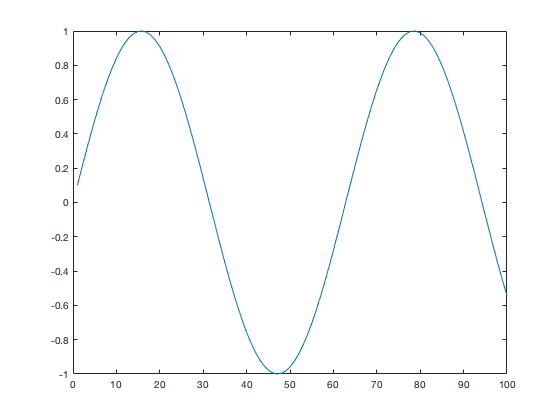

plot(t,y);

Note that: For plot(x,y), if x or y is a matrix, then the vector is plotted versus the rows or columns of the matrix, whichever line up.  

Plot titles, axes labels, and changing the style of your line

Make a new figure:

figure 

Make your plot line look different: 

g. = green dots (help [plot] for more)

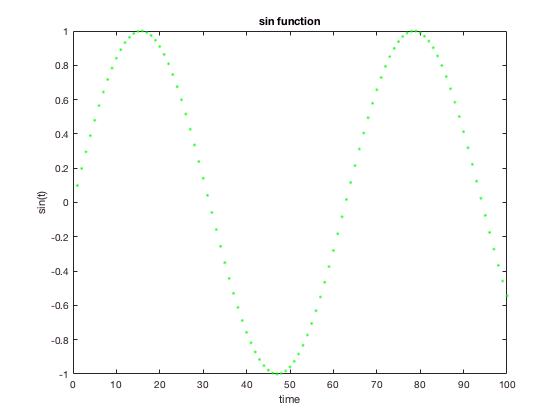

plot(t,y,'g.')
title('sin function')
xlabel('time')
ylabel('sin(t)')

To load a file using the command window, the file must be in your path directory:

%load sample_trace  

Sample_trace enters your workspace as 'v'.  V = time (index), 2 neurons (2 columns)

Using the size function:

size(v) 

ans =         1000           2


'v' is a 100 row x 2 column matrix

Plotting matrix v - all rows, column/neuron 1 - against the index (time):

figure
plot(v(:,1))

Too keep working on the same figure:

hold on

 Plot 2nd column in green:

plot(v(:,2),'g');

Add labels:

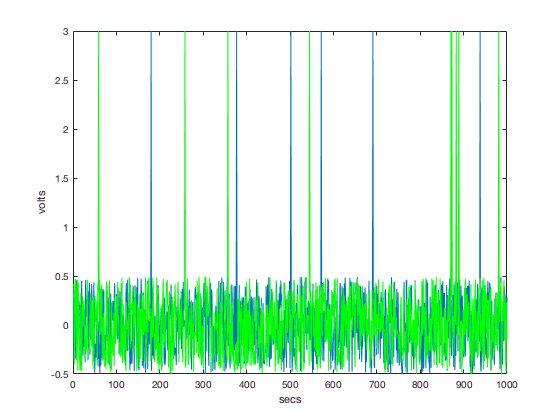

xlabel('secs')
ylabel('volts')

Bar Graphs

Making a bar graph for a vector

First, make the vector:


firingRate = [12 18 10];
figure 

Bar Function plots array elements vs index in bar graph form:

bar(firingRate)

Add title:

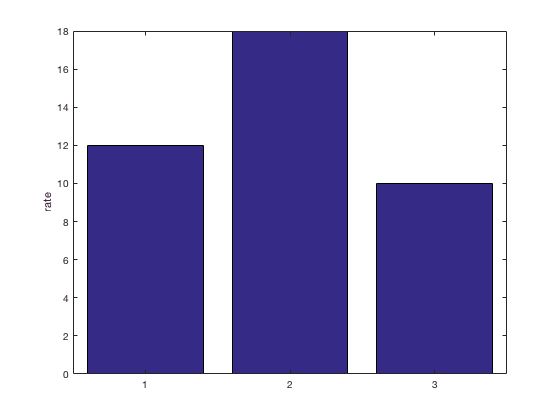

ylabel('rate')

Making a bar graph for a matrix:

figure

'Scores' is a 5 (rows) x 3 (columns) matrix. The output of bar(scores) is elements in each row grouped by column plotted against the index:

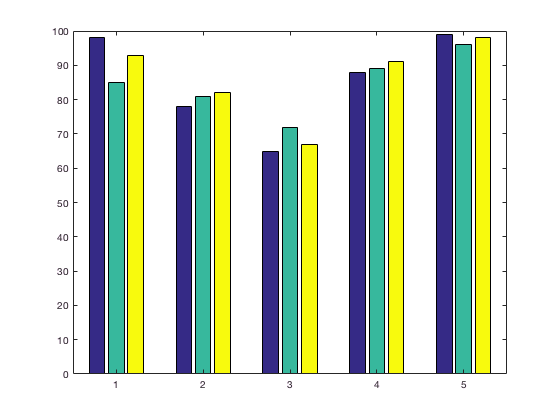

bar(scores)

#Change